# Small-Signal Stability package

This package implements Small-Signal Stability (sss) related algorithms, visualization and anlysis tools.

## Introduction

This package build on OOPSAT ([GitHub link](https://github.com/timonviola/OOPSAT)) and utilizes power-flow and small-signal stability features.

The followings is a short introduction of the usage where we are going to

- invoke an OOPSAT instance

- load a power system case file

- execute a load-flow

- execute sss analysis

- and analyse the results

### Invoke OOPSAT

ps = psat('command_line_psat',true,'nosplash',true);
ps

ps =   psat with properties:

    Settings: [1×1 struct]
         Fig: [1×1 struct]
        Path: [1×1 struct]
        File: [1×1 struct]
         Hdl: [1×1 struct]
      clpsat: [1×1 struct]
     History: [1×1 struct]
    Snapshot: [1×1 struct]
       Theme: [1×1 struct]
      Source: [1×1 struct]
         jay: 0.0000 + 1.0000i
        Comp: [1×1 struct]
       Algeb: []
       Buses: []
       Initl: []
       Param: []
       Servc: []
       State: []
      Varout: [1×1 struct]
     Varname: [1×1 struct]
         DAE: [1×1 struct]
         LIB: [1×1 struct]
         SNB: [1×1 struct]
         OPF: [1×1 struct]
         CPF: [1×1 struct]
        SSSA: [1×1 struct]
         PMU: [1×1 struct]
        OMIB: [1×1 struct]
        GAMS: [1×1 struct]
     UWPFLOW: [1×1 struct]
          LA: [1×1 struct]
       EQUIV: [1×1 struct]
         Bus: [1×1 BUclass]
       Areas: [1×1 ARclass]
     Regions: [1×1 ARclass]
        Line: [1×

### Load a case file

ps.runpsat('case_files/d_case14.m','data')

### Execute a power flow

ps.runpsat('pf')

Load data from file...
   
Newton-Raphson Method for Power Flow Computation
Data file "C:\Users\Timon\OneDrive - Danmarks Tekniske Universitet\Denmark\DTU\2019_20_II\software\case_files/d_case14.m"
Writing file "fm_call" ...
PF solver: Newton-Raphson method
Single slack bus model
Iteration = 1     Maximum Convergency Error = 0.40086
Iteration = 2     Maximum Convergency Error = 0.015935
Iteration = 3     Maximum Convergency Error = 0.00024325
Iteration = 4     Maximum Convergency Error = 5.7396e-08
Initialization of Synchronous Machines completed.
Initialization of Automatic Voltage Regulators completed.
Power Flow completed in 0.176 s


### Small-signal stability analysis

ps.fm_abcd();

Computation of input/output matrices A,B,C,D:
   
[Delta dx/dt] = [A] [Delta x] + [B] [Delta u]
    [Delta y] = [C] [Delta x] + [D] [Delta u]
   
These matrices are stored in structure obj.LA.
* * * No turbine governor found
* * * No SVC device found
* * * No TCSC device found
* * * No Statcom device found
* * * No SSSC device found
* * * No UPFC device found
* * * No HVDC device found
Computation of input/output matrices completed.


As = ps.LA.a;
[wn, zeta, p] = SmallSignalStability.damp_(As);

### Analysis of the results

There are countless ways to analyse the results. This is just some simple visualization of the results.

#### Damping ratio

Check if the lowest undamped natural frequency is above the critical damping ratio limit

[stable, dr] = SmallSignalStability.checkSmallSignalStability(0.03,As)

stable = logical
   0

dr = -0.0906

### Plotting the results

[~,ax] = SmallSignalStability.plot.eigPlot(p,'shed',1000);

Using defaults: 
    'axh'    'decorators'    'scatterParams'
Discarded 6 values.


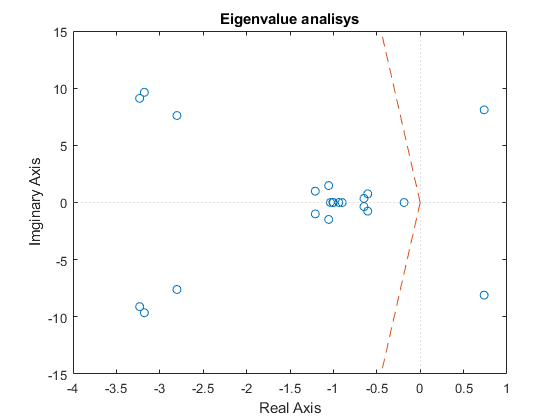

SmallSignalStability.plot.plotStabMargin(0.03);
ax.XLim = [-4,1];

The plot can be easily alterred, e.g. this snippet ads a pole pair to the plot:

% SmallSignalStability.plot.eigPlot([0+1i;0-1i],ax,'decorators',false...
%     ,'scatterParams',{'Marker','d','MarkerEdgeColor','g'});